clc; 
clf; 
clear all;

*Importing the dataset from the excel sheet*

[B,text] = xlsread('data.xlsx');

*Initialising the variable, 'Data' which basically has the extracted values of the dataset from the 3rd column*

Data = B(:,3:end);

*Initialising the variable, 'diagnosis' which basically has the extracted values of the dataset of the 2nd column which basically gives us the information whether a person has cancer or not*

diagnosis = B(:,2);

*We perform Principle component analysis (PCA) using Singular Value Decomposition (SVD)*

[U,S,V] = svd(Data,'econ'); 

*econ - economy size decomposition*

*If data matrix is mxn*

*If m is less -> it returns mxm matrix*

*If n is less -> it returns nxn matrix*

*If m = n -> it returns mxn matrix*

figure(1)
subplot(1,2,1)
semilogy(diag(S),'k-o','LineWidth',2.5) 

*Plotting the singular values on a log scale -> x axis - (number of columns (rank)), y axis - magnitude of log of the singular value*

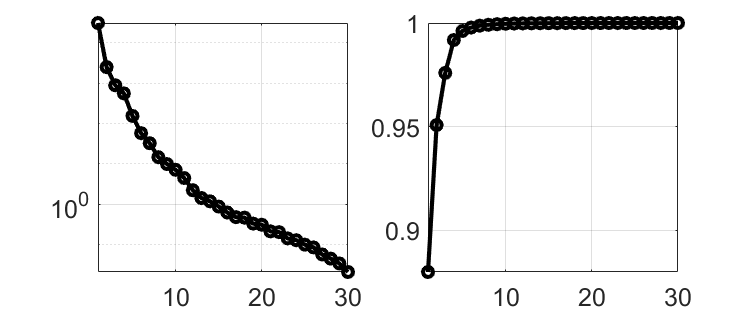

set(gca,'FontSize',15),axis tight, grid on
subplot(1,2,2) % to find the amount of data captured
plot(cumsum(diag(S))./sum(diag(S)),'k-o','LineWidth',2.5)
set(gca,'FontSize',15),axis tight, grid on

set(gcf,'Position',[1400 100 600 250])
 
figure(2)
hold on

*Taking 2 eigen genetic sequences (cancer or no cancer)*

for i=1:size(Data,1) 
     x = V(:,1)' * Data(i,:)';
     y = V(:,2)' * Data(i,:)';
     
     PC1(i) = x;
     PC2(i) = y;

     if (diagnosis(i) == 1)
         plot(x,y,'rx','LineWidth',3);
     else
         plot(x,y,'bo','LineWidth',3);
     end
end
xlabel('PC1'), ylabel('PC2')

*A new dataset having the values recorded for one new patient to predict whether the person has cancer or not*

NewData=[11.42, 20.38, 77.58, 386.1, 0.1425, 0.2839, 0.2414, 0.1052, 0.2597, 0.09744, 0.4956, 1.156, 3.445, 27.23, 0.00911, 0.07458, 0.05661, 0.01867, 0.05963, 0.009208, 14.91, 26.5, 98.87, 567.7, 0.2098, 0.8663, 0.6869, 0.2575, 0.6638, 0.173];

*We perform Principle component analysis (PCA) using Singular Value Decomposition (SVD) for the new data*

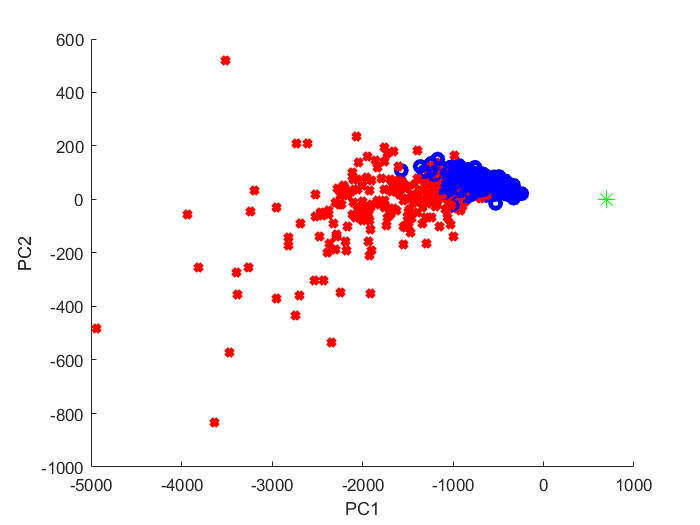

[U1,Z1,V1] = svd(NewData);
x = V1(:,1)' * NewData(1,:)';
y = V1(:,2)' * NewData(1,:)';
plot(x, y, 'g*', 'MarkerSize', 10)